# Parameters

N = 64; % OFDM subcarriers --> spilts available bandwidth into 64 narrowband subcarriers
M = 16; % 16-QAM --> 16 square complex constellation points 
k = log2(M); % bits/symbol --> 4 bits/symbols
numSymbols = 1e5; % Total no. of QAM symbols
cpLen = 16; % Each OFDM symbol is extended by coping its last 16 samples to front 

SNRdB_vec = 0:1:25; % Simulation will be run at values 0,1,2,...,25dB 
numSNR = length(SNRdB_vec);

# Transmitter

rng(1); % Set random number generator to a known state --> every run generates same bit sequence and noise pattern

% Bit Generation
txBits = randi( [0,1] , numSymbols*k , 1 ); % Generates a binary sequence 0f 0s and 1s of length (numSymbols*k)

% QAM Modulation
txQAM = qammod(txBits , M , ...
    'InputType','bit', ...
    'UnitAveragePower',true);

txQAM 

--> groups bits into blocks of k = log2(M)

--> maps each block to complex symbol

s = I +jQ

output of txQAM 

txQAM = {s_n} belongs to **C**

**Modulation = complex plane represensation of symbols**

% Reference symbol indices (for SER)
txSymIdx = qamdemod( txQAM , M , ...
    'OutputType','integer', ...
    'UnitAveragePower' , true);

txSymIdx

--> takes already modulated symbols and maps them back to symbol indices

s_n --> n 

where n belongs to {0,1,2,....M-1}

**We did this just for reference for SER evaluation**

# OFDM Modulation

numOFDM = ceil(numSymbols/N);
txQAM_padded = [txQAM; zeros(numOFDM*N - numSymbols , 1)];


$$numOFDM =  \frac{\text{No. of QAM symbols}}{N} $$


#### **OFDM converts a symbol bit stream into parallel frequency domain block**

#### **Each OFDM symbol carries N QAM symbol in parallel (one per subcarrier)**

% Serial to parallel conversion
dataMatrix = reshape(txQAM_padded , N  , numOFDM );
txIFFT = ifft(dataMatrix , N , 1);

Reshape data into OFDM symbol Matrix;


$$\left[ \matrix{X^{(1)}_{0} & X^{(2)}_{0} & ... \cr X^{(1)}_{1} & X^{(2)}_{1} & ... \cr ... & ... \cr X^{(1)}_{N-1} & X^{(2)}_{N-1} & ...} \right]$$


Each column -> one OFDM symbol

Each row -> one subcarrier

**Back to Time Domain:**

Compute IFFT


$$x^{m}[n] = \frac{1}{N} \sum_{k=0}^{N-1}X_{m}[k] e^{j2 \pi kn/N}$$


- Each QAM symbol modulates an orthogonal complex exponential

- Time domain OFDM symbol is sum of orthogonal subcarrier

- **OFDM is parallel modulation implemented efficiently using IFFT**

% Add cyclic Prefix
txOFDM_cp = [txIFFT(end - cpLen + 1 : end , : ); txIFFT];

Copies last cpLen samples of each OFDM symbols and prepends them to front

So each symbol becomes :


$$\left[ x[N - cpLen],\ \dots,\ x[N-1],\ x[0],\ \dots,\ x[N-1] \right]$$


% Parallel to Serial Conversion
txSignal = txOFDM_cp(:);
L = length(txSignal);

#### **txSignal is actual continuous time waveform that goes to DAC and RF chain**


$$\text{QAM symbols} \ \rightarrow^{\text{S/P}} \ \text{Frequency-domain OFDM symbols} \ \rightarrow^{\text{IFFT}} \ \text{Time-domain waveform} \ \rightarrow^{\text{CP}} \ \text{ISI-resilient signal} \ \rightarrow^{\text{P/S}} \ \text{Actual Baseband to DAC and RF Chain}$$


# Pulse Shaping

rolloff = 0.25;
span = 10;
sps = 4;

sps = 4 --> 4 samples per OFDM symbol

This is **oversampling:**

- Real pulse shaping filters are deined in Time Domain.

- Digital filters approximate them via oveersampling


$$T_{s} = \frac{T_{symbol}}{sps}$$


**Rolloff:**


$$B = \frac{1 + \alpha}{2T}$$


- a = 0 : brick wall

- a = 1 : very wide bandwidth

- a = 0.25 : practical trade-off

**span = 10**

Total filter length = span * sps + 1

pulse shaping filter are theoretically infinite.

we truncate them -> introduces approx. error 

rrc = rcosdesign(rolloff , span , sps , 'sqrt');
totalDelay = span*sps; % Group Delay
mfGain = sum(rrc.^2); % Matched Filter Gain

Generates RRC pulse:

p(t) such that $|P{f}|^{2}$ = Raised Cosine

Tx * Rx = Raised Cosine

- Transmitter uses RRC

- Receiver(Matched filter) uses RRC

- Combined response satisfies **Nyquist ISI free condition**

**mfGain = **$\sum_{n} |p[n]|^{2}$

The Energy gain for Matched Filter

Used for normalizing noise and maintain correct SNR

txUps = upsample(txSignal , sps); % Inserts sps - 1 zeros between samples --> prepares x[n] for pulse shaping convolution
txShaped = conv(txUps , rrc , 'full');


$$x_{tx}[n] = \sum_{k} x_{\uparrow}[k]p[n-k]$$


Now x[n] has :

- smoothed sharp transitions

- Limited Bandwith

- Reduced Spectral sidelobes

Without pulse shaping

- OFDM samples are **rectangular pulses**

- Spectrum has **large sinc sidelobes**

- Unrealistic for real transmitters

With RRC pulse shaping:

- Signal is **bandlimited**

- Matched filter optimality holds

- ISI-free sampling is possible (after Rx filtering)


$$\hspace{1.5cm}\text{QAM} \to \text{OFDM} \to \text{Upsample} \to \text{RRC} \to \text{Physical baseband waveform}$$



$$\underbrace{\quad\quad\quad\quad\quad\quad\quad}_{\text{Pulse shaping}}$$



$$\text{QAM symbols} \ \rightarrow^{\text{S/P}} \ \text{Frequency-domain OFDM symbols} \ \rightarrow^{\text{IFFT}} \ \text{Time-domain waveform} \ \rightarrow^{\text{CP}} \ \text{ISI-resilient signal} \ \rightarrow^{\text{P/S}} \ \text{Tx Signal with OFDM samples(rect. pulses)}\to \text{Pulse shaping} \to \text{Physical baseband waveform}$$


# Fixed Point

wordLen = 16;
fracLen = 12;

Total Bits = 16

Fractional Bits = 12

Integer Bits (including sign) = 16 -12 = 4

So numbers are reoresented as:


$$x = -b_{15}2^{3} + \sum_{i=0}^{11}b_{i}2^{-i}$$


Dynamic Range:

###                             [ -8 , 7.9998 ]

T = numerictype(1, wordLen , fracLen);
F = fimath('RoundingMethod','Nearest','OverflowAction','Saturate'); % Quantisation Error --> minimizes mean-squared quantisation noise

tx_fixed = fi(txSignal , T , F); % introduces Quantisation Noise

% quantised signal applied pulse shaping
txUps_fx = upsample(double(tx_fixed) , sps);
txShaped_fx = conv(txUps_fx , double(rrc) , "full");

This Block mimics:


$$\text{Digital baseband } \rightarrow^{fixed-point}\text{ DAC-like Signal}$$


# Results Storage

BER_float = zeros(numSNR , 1);
SER_float = zeros(numSNR , 1);
BER_fixed = zeros(numSNR , 1);
SER_fixed = zeros(numSNR , 1);

# Simulation Loop

for iSNR = 1:numSNR
    SNRdB = SNRdB_vec(iSNR);

    % -------- Floating Point Path --------
    noisy_f = awgn(txShaped , SNRdB , 'measured'); % AWGN channel --> adds Noise

    rxMF_f = conv(noisy_f , rrc , "full"); % Matched Filtering
    
    % Remove filter Group Deley + downsample + Normalize MF gain
    rxRec_f = rxMF_f(totalDelay+1 : sps : totalDelay+L*sps);
    rxSignal_f = rxRec_f / mfGain;

    % Serial to Parallel + Remove CP + FFT per symbol
    rxMat_f = reshape(rxSignal_f , N+cpLen , []);
    rxFFT_f = fft(rxMat_f(cpLen+1:end,:) , N , 1);

    % QAM Demodulation
    % Corresponds to MAP Detection under AWGN
    % Minimum Distance Regions

    % BER
    rxBits_f = qamdemod(rxFFT_f(:), M , ....
        'OutputType','bit','UnitAveragePower',true);
    rxBits_f = rxBits_f(1:length(txBits));

    % SER
    rxSymIdx_f = qamdemod(rxFFT_f(:), M , ....
        'OutputType','integer','UnitAveragePower',true);
    rxSymIdx_f = rxSymIdx_f(1:numSymbols);

    % Error Metrices
    [~ , BER_float(iSNR)] = biterr(txBits , rxBits_f);
    SER_float(iSNR) = mean(rxSymIdx_f ~= txSymIdx);

    % -------- Fixed Point Path --------

    noisy_fx = awgn(txShaped_fx, SNRdB, 'measured');
    rxMF_fx = conv(noisy_fx, double(rrc), 'full');
    rxRec_fx = rxMF_fx(totalDelay+1:sps:totalDelay+L*sps);
    rxSignal_fx = rxRec_fx / mfGain;

    rxMat_fx = reshape(rxSignal_fx, N+cpLen, []);
    rxFFT_fx = fft(rxMat_fx(cpLen+1:end,:), N, 1);

    rxBits_fx = qamdemod(rxFFT_fx(:), M, ...
        'OutputType','bit','UnitAveragePower',true);
    rxBits_fx = rxBits_fx(1:length(txBits));

    rxSymIdx_fx = qamdemod(rxFFT_fx(:), M, ...
        'OutputType','integer','UnitAveragePower',true);
    rxSymIdx_fx = rxSymIdx_fx(1:numSymbols);

    [~, BER_fixed(iSNR)] = biterr(txBits, rxBits_fx);
    SER_fixed(iSNR) = mean(rxSymIdx_fx ~= txSymIdx);

    % Logging
    fprintf('SNR=%2d dB | Float: BER=%g SER=%g | Fixed: BER=%g SER=%g\n', ...
        SNRdB, BER_float(iSNR), SER_float(iSNR), ...
        BER_fixed(iSNR), SER_fixed(iSNR));
end

SNR= 0 dB | Float: BER=0.140845 SER=0.47923 | Fixed: BER=0.141818 SER=0.48178
SNR= 1 dB | Float: BER=0.11937 SER=0.418 | Fixed: BER=0.118568 SER=0.41567
SNR= 2 dB | Float: BER=0.0978725 SER=0.35279 | Fixed: BER=0.097565 SER=0.35089
SNR= 3 dB | Float: BER=0.0777625 SER=0.28751 | Fixed: BER=0.0771325 SER=0.28541
SNR= 4 dB | Float: BER=0.05869 SER=0.2216 | Fixed: BER=0.0584 SER=0.22041
SNR= 5 dB | Float: BER=0.0423075 SER=0.16193 | Fixed: BER=0.042195 SER=0.16132
SNR= 6 dB | Float: BER=0.0278375 SER=0.10818 | Fixed: BER=0.0280675 SER=0.10933
SNR= 7 dB | Float: BER=0.01679 SER=0.06601 | Fixed: BER=0.0171425 SER=0.06729
SNR= 8 dB | Float: BER=0.0089 SER=0.03524 | Fixed: BER=0.0091025 SER=0.03596
SNR= 9 dB | Float: BER=0.0045825 SER=0.01829 | Fixed: BER=0.004435 SER=0.01762
SNR=10 dB | Float: BER=0.00178 SER=0.00708 | Fixed: BER=0.0017475 SER=0.00697
SNR=11 dB | Float: BER=0.000585 SER=0.00234 | Fixed: BER=0.000605 SER=0.00242
SNR=12 dB | Float: BER=0.0001225 SER=0.00049 | Fixed: BER=0.00019

# Plots

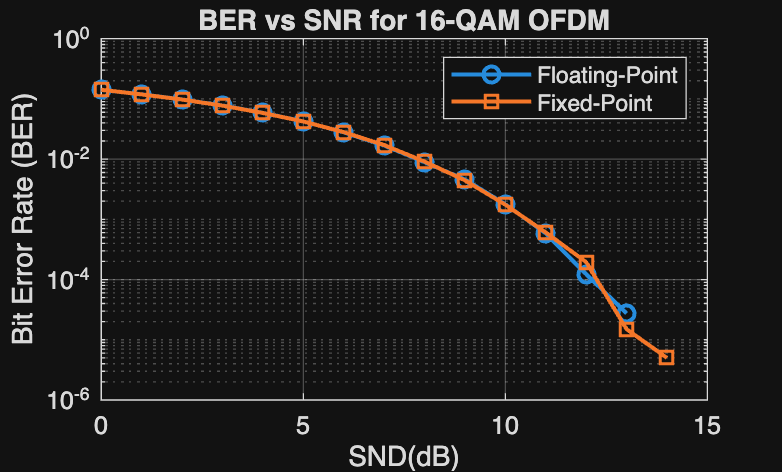

% BER
figure;
semilogy(SNRdB_vec, BER_float , '-o' , 'LineWidth', 1.5);
hold on;
semilogy(SNRdB_vec ,BER_fixed , '-s' ,'LineWidth', 1.5);
grid on;

xlabel('SND(dB)');
ylabel('Bit Error Rate (BER)');
legend('Floating-Point' , 'Fixed-Point');
title('BER vs SNR for 16-QAM OFDM');

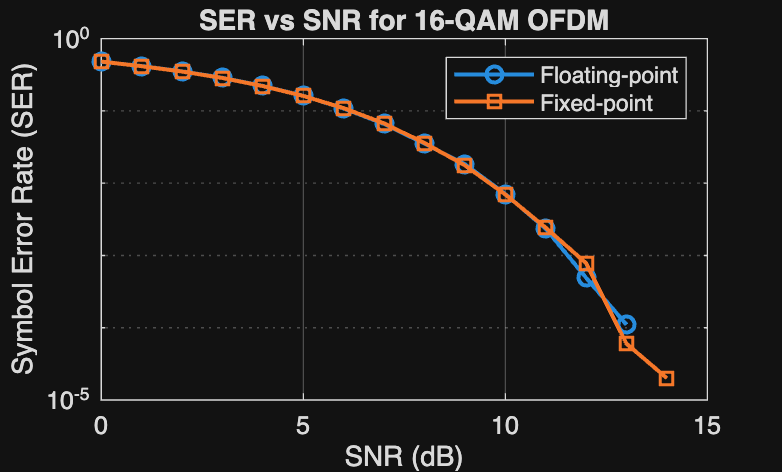


% SER
figure; 
semilogy(SNRdB_vec, SER_float,'-o','LineWidth',1.5); hold on;
semilogy(SNRdB_vec, SER_fixed,'-s','LineWidth',1.5);
grid on;

xlabel('SNR (dB)');
ylabel('Symbol Error Rate (SER)');
legend('Floating-point','Fixed-point');
title('SER vs SNR for 16-QAM OFDM');

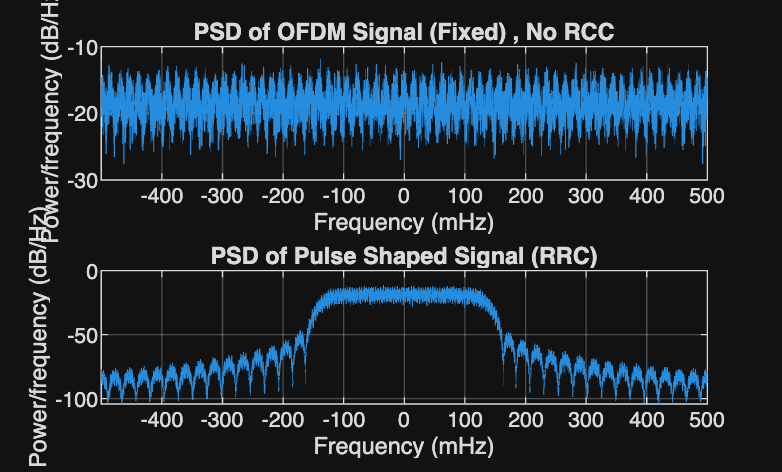


% PSD Comparison
figure;
subplot(2,1,1);
pwelch(double(tx_fixed) , [] , [] , [] , 1 , 'centered');
title('PSD of OFDM Signal (Fixed) , No RCC');
grid on;

subplot(2,1,2);
pwelch(txShaped,[],[],[],1,'centered');
title('PSD of Pulse Shaped Signal (RRC)'); 
grid on;

# Constellation at different SNR

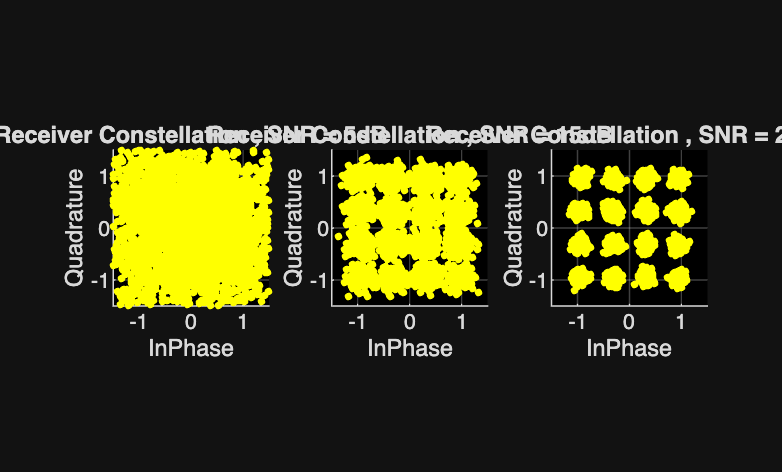

snrList = [5 , 15 , 20]; % SNR values
numPts = 3000; % points to visualize

figure;
for ksnr = 1:length(snrList)
    SNRdB = snrList(ksnr);

    % QAM symbols with AWGN
    rxQAM = awgn(txQAM ,SNRdB ,'measured');

    % Plot
    subplot(1,3,ksnr);
    scatter(real(rxQAM(1:numPts)) , imag(rxQAM(1:numPts)), ...
        8 , 'y' , 'filled');

    grid on;
    axis square;
    xlim([-1.5 , 1.5]);
    ylim([-1.5 , 1.5]);
    set(gca , 'Color' , 'k');

    xlabel('InPhase');
    ylabel('Quadrature');
    title(['Receiver Constellation , SNR = ', num2str(SNRdB) , 'dB']);
end